# Force Sensor Calibration

load('forceSensorData.mat');
% K Value: 2 (Set by course)
K = 2;
[forceCalibrCurve, forceCalibrGoodness] = fit(voltageForceCalibrationData, forceCalibrationData, 'poly1');
forceCalibrGain = forceCalibrCurve.p1; % N/V
forceCalibrOffset = forceCalibrCurve.p2; % N

## Uncertainty Calcs

% Voltage Offset Calc
voltageForceCalibrOffset = -(forceCalibrOffset)./(forceCalibrGain) % V

voltageForceCalibrOffset = -0.0240

forceSTD = forceCalibrGoodness.rmse; % N
forceUncertainty = forceSTD.*K; % N
fprintf("Prediction Interval (K = 2): %.4f N\n", forceUncertainty);

Prediction Interval (K = 2): 549.8632 N


## Visualizing Sensor Calibration

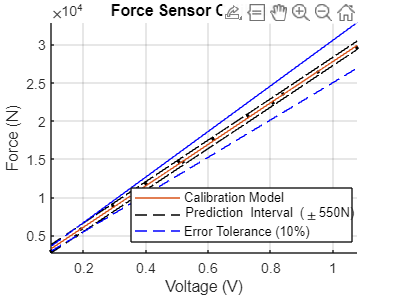

figure
hold on; grid on;
scatter(voltageForceCalibrationData, forceCalibrationData, 50, 'k.')
% Add Calibration Model
forceFitData = feval(forceCalibrCurve, voltageForceCalibrationData);
forceCalibrCurvePlot = plot(voltageForceCalibrationData, forceFitData);
% Add Prediction Interval
forceUncertaintyPlot = plot(voltageForceCalibrationData, forceFitData + forceUncertainty, 'k--');
plot(voltageForceCalibrationData, forceFitData - forceUncertainty, 'k--')
% Add Tolerance Interval
forceTolerancePlot = plot(voltageForceCalibrationData, forceFitData.*1.10, 'b--');
plot(voltageForceCalibrationData, forceFitData.*0.90, 'b--');
legend([forceCalibrCurvePlot forceUncertaintyPlot forceTolerancePlot], {'Calibration Model', 'Prediction Interval (\pm550N)', 'Error Tolerance (10%)'}, 'Location', 'Best')
title('Force Sensor Calibration')
xlabel('Voltage (V)')
ylabel('Force (N)')
axis tight